clc
clear all


close all
% a alpha d theta
% DHparameter=[4 pi/2 0 pi/2;
%              4 pi/2 0 pi/2;
%              4 0 0 pi/2] / 10

% DHparameter=[0.4 pi/2 0 0;
%              0 pi/2 0 0;
%              0 0 0 0];
DHparameter=[0 pi/2 0 0;
             0 pi/2 0 0;
             0 0 0 0];

% DHparameter=[0 0 0 0;
%              0 pi/2 0 pi/2;
%              0 -pi/2 0 -pi/2]

% Defining a Robot Rigid Body Tree 
robot = rigidBodyTree("MaxNumBodies",3,"DataFormat","column");

% Setting the Gravity matrix w.r.t to the base frame of robot.
robot.Gravity = [0 0 -9.81];

% Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
joint1.HomePosition = deg2rad(25);
joint1.PositionLimits = [deg2rad(15) deg2rad(95)];

body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','prismatic');
joint2.HomePosition = 0.2;
joint2.PositionLimits = [0 1];
% 
body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
% joint3.HomePosition = pi/4;

% Settings the transformations to each joint with DH parameter.
% Assigning the joint of each link with the object 

setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;


addBody(robot,body1,'base');
addBody(robot,body2,'Body1');
addBody(robot,body3,'Body2');

showdetails(robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2     prismatic            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   
--------------------


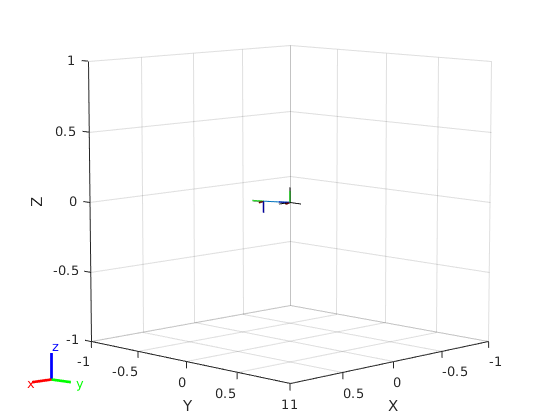



figure
show(robot,"Collisions","on","Visuals","on");

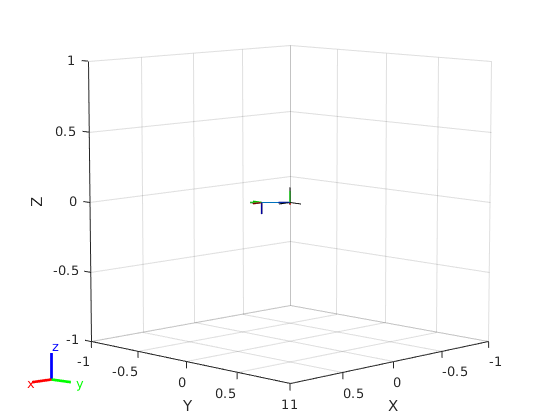


figure
show(robot,[pi/4 0.2 pi/4]',"Collisions","on","Visuals","on");

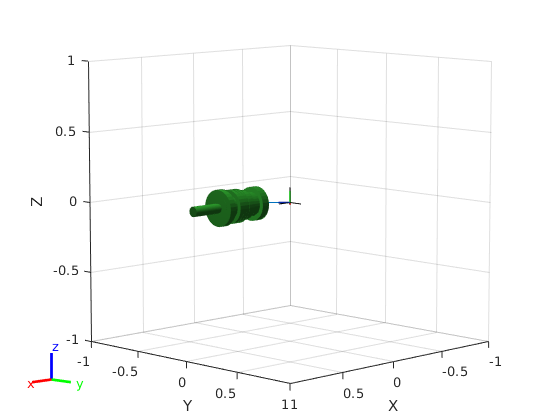


% weights = [0 0 0 1 1 1];
% ik = inverseKinematics('RigidBodyTree',robot);
% startVector = trvec2tform([0.4 0 0.4]);
% [qStart, solinfoStart] = ik("Body3",startVector,weights,robot.homeConfiguration)
% 
% figure
% show(robot,qStart);

axleShaft = collisionCylinder(0.036, 0.66);
axleShaft.Pose = trvec2tform([0 0 0.33]);

axleLarge = collisionCylinder(0.090, 0.384);
axleLarge.Pose = trvec2tform([0 0 0.192+0.04]);

bevel1 = collisionCylinder(0.120, 0.06);
bevel1.Pose = trvec2tform([0 0 0.03+ 0.045]);

spurShaft1 = collisionCylinder(0.106, 0.05);
spurShaft1.Pose = trvec2tform([0 0 0.025+0.05+0.120]);

spurShaft2 = collisionCylinder(0.120, 0.05);
spurShaft2.Pose = trvec2tform([0 0 0.025+0.05+0.120+0.066]);

spurShaft3 = collisionCylinder(0.130, 0.05);
spurShaft3.Pose = trvec2tform([0 0 0.025+0.384+0.04-0.05]);

bevel2 = collisionCylinder(0.120, 0.06);
bevel2.Pose = trvec2tform([0 0 0.03+0.05+0.120+0.066+0.025]);

mainshaft = [axleShaft axleLarge bevel1 bevel2 spurShaft1 spurShaft2 spurShaft3];


for i = 1:robot.NumBodies
    clearCollision(robot.Bodies{i})
end


for i=1:length(mainshaft)
   addCollision(robot.Bodies{end},mainshaft(i), axang2tform([0 1 0 pi/2]))
end

figure
show(robot,[pi/4 0.2 pi/4]',"Collisions","on","Visuals","on");

% move robot
% figure("WindowState","fullscreen")
% 
% axis equal
% hold on
% grid on
% for i=1:20:360
%     show(robot, [deg2rad(i) 1 deg2rad(i)]',"PreservePlot",false,"Collisions","on");
%     axis([-0.5 0.5 -0.5 0.5 -0.5 0.5].*3)
%     view([1 1 1])
%     drawnow
%     pause(0.001)
% end

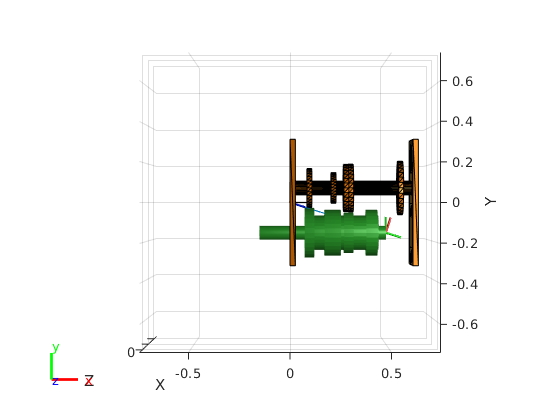

figure
startAngle = 72.5;
goalAngle = 55;

startConfig = [deg2rad(startAngle) 0.525 -pi+deg2rad(startAngle)]';
goalConfig = [deg2rad(goalAngle) 0.725 -pi+deg2rad(goalAngle)]';

show(robot,startConfig,'Collisions','on','Visuals','off'); hold on;
view([0.00 90.00])
xlim([-0.74 0.74])
ylim([-0.74 0.74])
zlim([-0.74 0.74])

% get environment
thickness = 0.0275;
[primaryhshaft, plate1, plate2] = getEnvironment(thickness);

% figure
for i=1:length(primaryhshaft)
    primaryhshaft(i).Pose = trvec2tform([0 0.076 0])* axang2tform([0 0 1 pi])*...
                                axang2tform([0 -1 0 pi/2]) * primaryhshaft(i).Pose;
    show(primaryhshaft(i)); hold on;
end



for i=1:length(plate1)
    plate1(i).Pose = axang2tform([1 0 0 -pi/2])*trvec2tform([thickness/2 0 0])*...
                        axang2tform([0 -1 0 pi/2]) * plate1(i).Pose;
    show(plate1(i)); hold on;
    

    
    
    plate2(i).Pose = axang2tform([1 0 0 -pi/2])*trvec2tform([0.660-thickness/2 0 0])*...
                        axang2tform([0 -1 0 pi/2]) * plate2(i).Pose;
    show(plate2(i)); hold on;
end


worldObjects = {};

for i=1:length(primaryhshaft)
    worldObjects{end+1} = primaryhshaft(i);
end

for i=1:length(plate1)
    worldObjects{end+1} = plate1(i);
end

for i=1:length(plate2)
    worldObjects{end+1} = plate2(i);
end

isColliding = checkCollision(robot,startConfig,worldObjects,'IgnoreSelfCollision','on')

isColliding = logical
   0


% plan the path

rrt = manipulatorRRT(robot, worldObjects);
rrt.MaxConnectionDistance = 0.05;
rrt.MaxIterations = 10000;

if 0
    disp("Calculating path");
    path = plan(rrt,startConfig',goalConfig')
else
    load("path.mat")
end

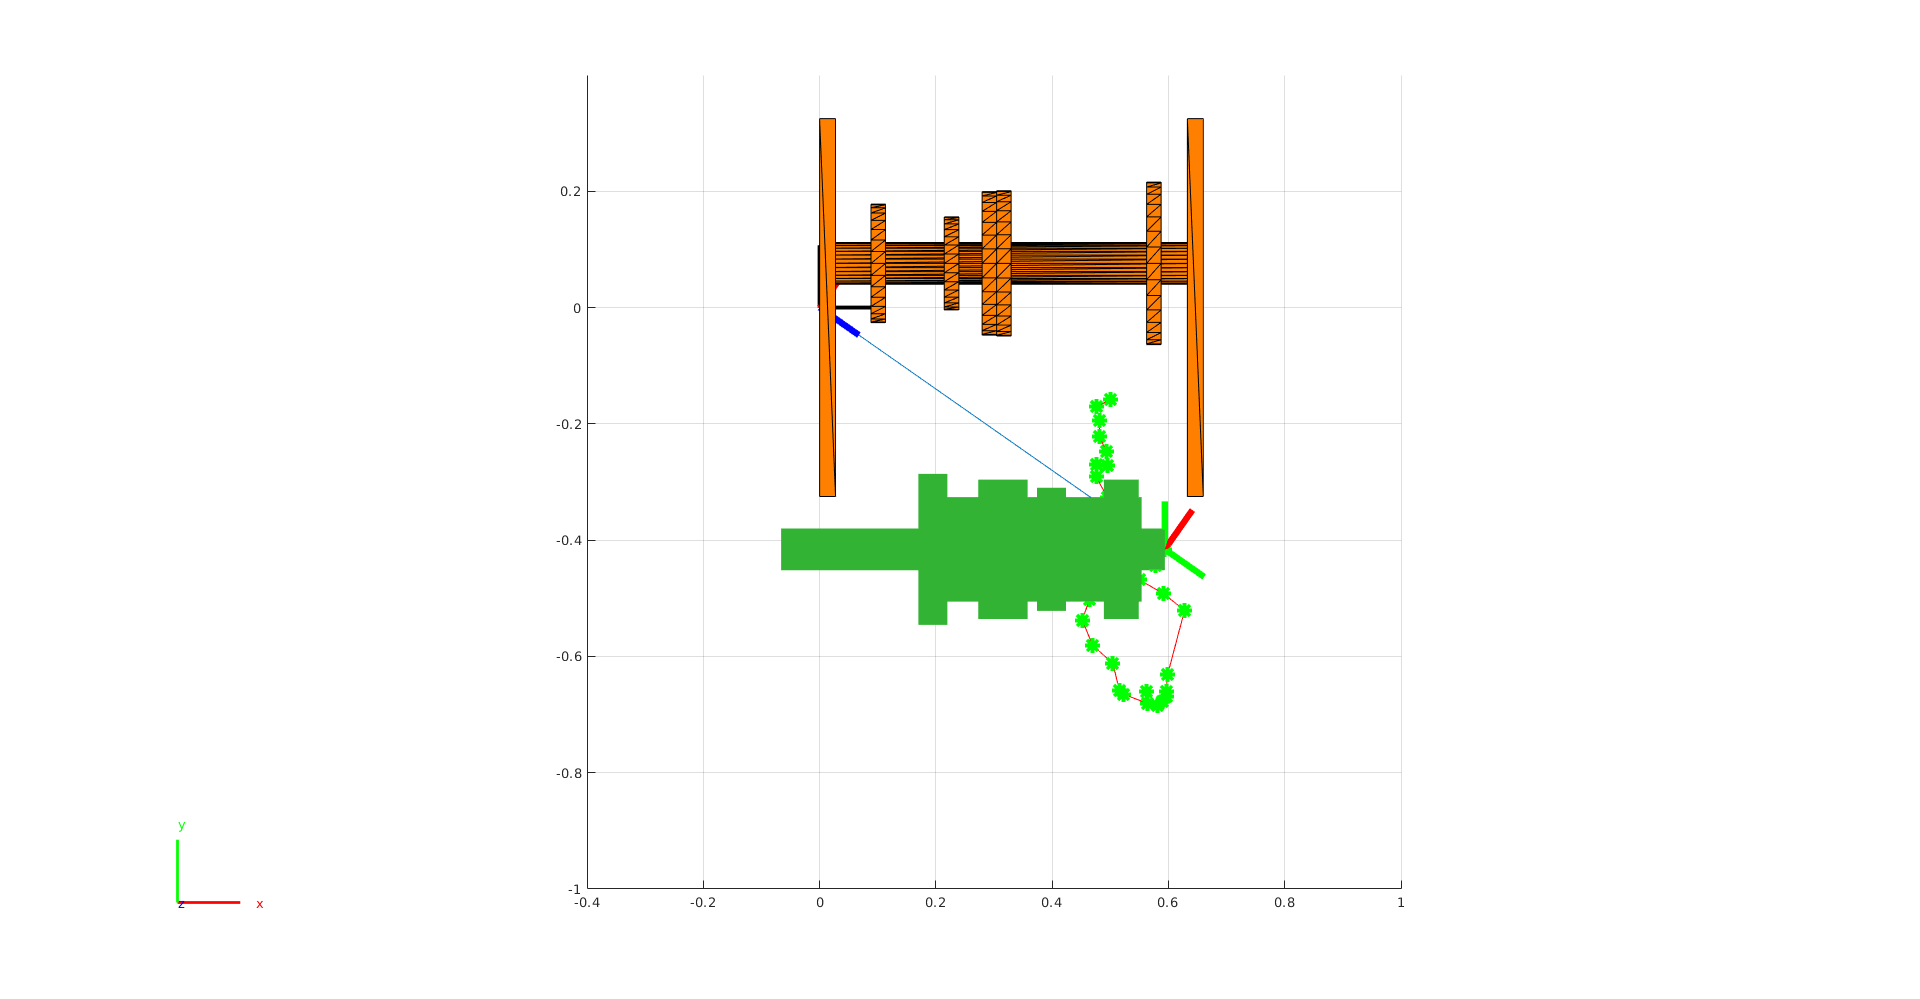

save('path.mat',"path")
% move robot
close all;
figure("WindowState","maximized")

axis equal
hold on
grid on

axis([-0.2 0.5 -0.5 0.2 -0.5 0.5].*2)
% view([1 1 1])
view([0 0 1])
% view([150 60])

for i=1:length(primaryhshaft)
    show(primaryhshaft(i))
end
 
for i=1:length(plate1)
    show(plate1(i))
end

for i=1:length(plate2)
    show(plate2(i))
end

eePath = [];

for i=1:length(path)
    show(robot, path(i,:)',"PreservePlot",false,"Collisions","on");
    eePath(end+1,:) = tform2trvec(getTransform(robot,path(i,:)','Body3'));
    plot3(eePath(:,1), eePath(:,2), eePath(:,3), 'r');
    drawnow
    pause(0.1)
end
plot3(eePath(:,1), eePath(:,2), eePath(:,3), '*',"MarkerSize",10,"Color",[0 1 0], "LineWidth",3);

Functions

function [primaryshaft, plate1, plate2] = getEnvironment(thickness)
    axle = collisionCylinder(0.036, 0.660);
    axle.Pose = trvec2tform([0 0 0.33]);
    
    spur1 = collisionCylinder(0.102, 0.025);
    spur1.Pose = trvec2tform([0 0 0.025+0.076]);
    
    spur2 = collisionCylinder(0.08, 0.025);
    spur2.Pose = trvec2tform([0 0 0.025+0.202]);
    
    spur3 = collisionCylinder(0.1235, 0.025);
    spur3.Pose = trvec2tform([0 0 0.025+0.267]);
    
    spur4 = collisionCylinder(0.125, 0.025);
    spur4.Pose = trvec2tform([0 0 0.025+0.267+0.025]);
    
    spur5 = collisionCylinder(0.140, 0.025);
    spur5.Pose = trvec2tform([0 0 0.025+0.660-0.06-0.05]);
    
    
    
    % plates
       
    column = collisionBox(0.650, 0.130, thickness);
    column.Pose = trvec2tform([0 0.145 0]);
    column2 = column.copy();
    column2.Pose = trvec2tform([0 -0.145 0]);
    
    beam1 = collisionBox(0.170, 0.160, thickness);
    beam1.Pose = trvec2tform([0.325-0.085 0 0]);
    
    beam2 = collisionBox(0.070, 0.160, thickness);
    beam2.Pose = trvec2tform([0.325-0.250-0.080-0.035 0 0]);
    
    beam3 = collisionBox(0.090, 0.160, thickness);
    beam3.Pose = trvec2tform([-0.325+0.045 0 0]);
    
    primaryshaft = [axle spur1 spur2 spur3 spur4 spur5];
    plate1 = [column column2 beam1 beam2 beam3];
    plate2 = [column.copy() column2.copy() beam1.copy() beam2.copy() beam3.copy()];
end